clear
% Read img file
img = imread("../db/DB0/db0_2.jpg");

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

%Find eyes and a mouth
eyes = eyemap(img_gw);
eye_mask = eyemask(eyes) & face_mask;

mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask)

x = 321

y = 383


[indexX,indexY] = eye_index(eye_mask)

indexX =     69   154   154   177   190   194   229   240   268   329   316   391   376


indexY =    350   516   152   273   410   235   354   128   411   242   575   449   379


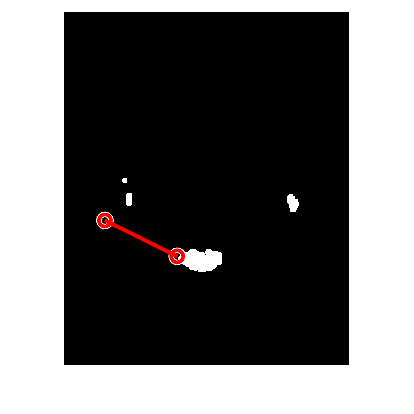

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


mouth_center = [x, y]; % replace with actual coordinates
[eye1 , eye2, angle] = findEyePair(indexX,indexY,mouth_center);

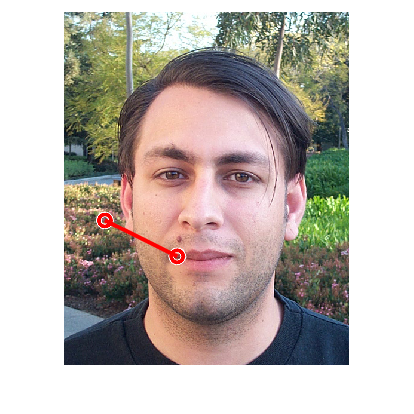


% Visualize the original image with detected eyes and mouth
figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r');